clear all;
close all;
clc;

% Añadir el camino de Cobra Toolbox
addpath('C:\Users\PC\OneDrive\Documentos\MATLAB\cobratoolbox')
savepath

% Eliminar manualmente el archivo de bloqueo si existe
lockFile = 'C:\Users\PC\OneDrive\Documentos\MATLAB\cobratoolbox\.git\modules\papers\shallow.lock';
if exist(lockFile, 'file')
    delete(lockFile);
    disp('Archivo de bloqueo eliminado.');
end

% Inicializa Cobra Toolbox
initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.45.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > TranslateSBML is installed and working properly.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] GUROBI_PATH: C:\gurobi1001\win64\matlab
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ...

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle 

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
Could not find installation of matlab, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek    

## Define paths and load necessary data

cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Thresholding/Local_gini');
currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
data = readtable("data_TPM.xlsx");
h_k_g = readtable('NM2ENSG.xlsx');
housekeep_react_enz_eis = load('housekeep_react_enz_eis.mat');
housekeep_react_enz_eis = housekeep_react_enz_eis.hk_reactions_unique;
new_HKG_list = readtable('ENS_ID_HKG.xlsx');
new_HKG_list_enz = load('housekeep_react_enz_new.mat');
new_HKG_list_enz = new_HKG_list_enz.hk_reactions_unique;
test_HKG = readtable('journal.pcbi.1010295.s014.xlsx', 'Sheet','Human');
test_HKG = table2cell(test_HKG);
HKG_list_enz_test = load('housekeep_react_enz_test.mat');
HKG_list_enz_test = HKG_list_enz_test.hk_reactions_unique;
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
model_Alicia = load('SysBio_COBRA_v1.17_consensus1.mat');
model_Alicia = model_Alicia.myModel;
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes; % ENSEMBL_IDs of the genes in the model
model_genes = model.genes;
cd(currentFolder);

## Preprocess data

Ensembl_id = data(:, 1);
NamesSample = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
logged_data = log10(data_to_log + 2); % Normalize the data (+1 to avoid having 0 values) 

% Create the new table with normalized data
log_data = [Ensembl_id, array2table(logged_data)]; 
log_data.Properties.VariableNames(2:end) = NamesSample; 
log_data.Properties.VariableNames{1} = 'gene'; 


## Extract metabolic gene expression from both pruned and unpruned models

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UNPRUNED MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
geneExpressionMatrix = [];
for i = 1:width(NamesSample)
    log_data.value = log_data{:, i + 1};
    [geneList, geneExpression] = findUsedGenesLevels(model, log_data); 
    geneExpressionMatrix = [geneExpressionMatrix, geneExpression'];
    log_data.value = [];
end

% Convert results into a table
metabolic_genes = array2table(geneExpressionMatrix, 'RowNames', geneList, 'VariableNames', NamesSample);
metabolic_genes = rmmissing(metabolic_genes, 'MinNumMissing', size(metabolic_genes, 2)); 
save('metabolic_genes.mat', 'metabolic_genes')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PRUNED MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
geneExpressionMatrix_P = [];
for i = 1:width(NamesSample)
    log_data.value = log_data{:, i + 1}; 
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); 
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

% Convert results into a table
metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', NamesSample);
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); 
save('metabolic_genes_P.mat', 'metabolic_genes_P')

## Housekeeping reactions

hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));
results_HKReact = findRxnsFromGenes_Alicia(model_p, hkg_met);

Input: string of single gene or cell array of multiple genes



fields = fieldnames(results_HKReact);
housekeep_react = {};
for i = 1:length(fields)
    field = fields{i};
    cellArray = results_HKReact.(field);
    for j = 1:size(cellArray, 1)
        firstcol = cellArray{j, 1};
        housekeep_react{end+1, 1} = firstcol;
    end
end
housekeep_react_unique = unique(housekeep_react);
disp(housekeep_react_unique);

    {'MAR00001'}
    {'MAR00003'}
    {'MAR00005'}
    {'MAR00006'}
    {'MAR00010'}
    {'MAR00067'}
    {'MAR00080'}
    {'MAR00091'}
    {'MAR00113'}
    {'MAR00114'}
    {'MAR00115'}
    {'MAR00117'}
    {'MAR00118'}
    {'MAR00121'}
    {'MAR00122'}
    {'MAR00129'}
    {'MAR00133'}
    {'MAR00153'}
    {'MAR00154'}
    {'MAR00155'}
    {'MAR00158'}
    {'MAR00164'}
    {'MAR00167'}
    {'MAR00170'}
    {'MAR00173'}
    {'MAR00176'}
    {'MAR00179'}
    {'MAR00183'}
    {'MAR00187'}
    {'MAR00188'}
    {'MAR00190'}
    {'MAR00191'}
    {'MAR00192'}
    {'MAR00195'}
    {'MAR00196'}
    {'MAR00199'}
    {'MAR00200'}
    {'MAR00203'}
    {'MAR00204'}
    {'MAR00208'}
    {'MAR00209'}
    {'MAR00212'}
    {'MAR00213'}
    {'MAR00216'}
    {'MAR00217'}
    {'MAR00225'}
    {'MAR00226'}
    {'MAR00232'}
    {'MAR00233'}
    {'MAR00236'}
    {'MAR00237'}
    {'MAR00240'}
    {'MAR00241'}
    {'MAR00244'}
    {'MAR00245'}
    {'MAR00248'}
    {'MAR00249'}
    {'MAR00254'}
    {'MAR00255

## Start plotting and parallel processing

delete(gcp('nocreate'));
parpool('local');

Starting parallel pool (parpool) using the 'Processes' profile ...
24-Jun-2024 11:45:02: Job Queued. Waiting for parallel pool job with ID 1 to start ...
24-Jun-2024 11:46:03: Job Queued. Waiting for parallel pool job with ID 1 to start ...
Connected to parallel pool with 4 workers.



numColumns = size(metabolic_genes, 2);
numIterations = 11; % From upper_p = 100 to 50, decrementing by 5 each time

% Preallocate matrices for results
HK_CG_G_all = zeros(numColumns, numIterations);
HK_CR_R_all = zeros(numColumns, numIterations);
HK_CG_G_recall_values_all = zeros(numColumns, numIterations);
HK_CR_R_recall_values_all = zeros(numColumns, numIterations);
HK_CR_R_recall_norm_all = zeros(numColumns, numIterations);
HK_CG_G_recall_norm_all = zeros(numColumns, numIterations);

mean_HK_CG_G_all = zeros(1, numIterations);
std_HK_CG_G_all = zeros(1, numIterations);
mean_HK_CG_G_recall_values_all = zeros(1, numIterations);
std_HK_CG_G_recall_values_all = zeros(1, numIterations);
mean_HK_CR_R_all = zeros(1, numIterations);
std_HK_CR_R_all = zeros(1, numIterations);
mean_HK_CR_R_recall_values_all = zeros(1, numIterations);
std_HK_CR_R_recall_values_all = zeros(1, numIterations);
mean_HK_CR_R_recall_norm_all = zeros(1, numIterations);
std_HK_CR_R_recall_norm_all = zeros(1, numIterations);
mean_HK_CG_G_recall_norm_all = zeros(1, numIterations);
std_HK_CG_G_recall_norm_all = zeros(1, numIterations)

std_HK_CG_G_recall_norm_all =      0     0     0     0     0     0     0     0     0     0     0




gene_names_P = metabolic_genes_P.Properties.RowNames;

% Crear una estructura base para expressionData fuera del bucle
expressionData.gene = gene_names_P;
expressionData.value = [];

index = 1; % Inicializamos el índice antes del loop
for upper_p = 100:-5:50
    lower_p = 100 - upper_p;
    disp(['upper_p = ', num2str(upper_p), ', lower_p = ', num2str(lower_p)]);
    
    [adjusted_matrix, IMR90_Y2_norm] = localGini_function(metabolic_genes_P, metabolic_genes, lower_p, upper_p);
    
    % Inicializamos matrices para almacenar los resultados de las 48 columnas
    HK_CG_G_all_temp = zeros(1, 48);
    HK_CG_G_recall_values_all_temp = zeros(1, 48);
    HK_CR_R_all_temp = zeros(1, 48);
    HK_CR_R_recall_values_all_temp = zeros(1, 48);
    HK_CR_R_recall_norm_all_temp = zeros(1, 48);
    HK_CG_G_recall_norm_all_temp = zeros(1, 48);
    
    % Convert expressionData.gene to a sliced variable
    expressionDataGene = expressionData.gene;
    
    parfor col = 1:48
        % Calculamos los valores de IMR90_Y2_CG y HK_CG_G_all
        IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm(:, col) >= 1);
        HK_CG_G_all_temp(col) = (length(IMR90_Y2_CG) / length(IMR90_Y2_norm(:, col))) * 100;
        HK_CG_G_rec = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
        HK_CG_G_recall = (length(HK_CG_G_rec) / length(hkg_met)) * 100;
        HK_CG_G_recall_values_all_temp(col) = HK_CG_G_recall;
        HK_CG_G_recall_norm = (HK_CG_G_recall/100) * (length(model_p.genes)/length(IMR90_Y2_CG))
        HK_CG_G_recall_norm_all_temp(col) = HK_CG_G_recall_norm
        
        % Preparar los datos de expresión
        expressionDataSample = struct();
        expressionDataSample.gene = expressionDataGene; % Use the sliced variable here
        expressionDataSample.value = IMR90_Y2_norm(:, col);
        
        IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionDataSample, false);
        
        IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);
        HK_CR_R_all_temp(col) = (length(IMR90_Y2_CR) / length(model_p.rxns)) * 100;
        HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
        HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
        HK_CR_R_recall_values_all_temp(col) = HK_CR_R_recall;
        HK_CR_R_recall_norm = (HK_CR_R_recall/100) * (length(model_p.rxns)/length(IMR90_Y2_CR));
        HK_CR_R_recall_norm_all_temp(col) = HK_CR_R_recall_norm;
    end
    
    % Calculamos la media y desviación estándar para cada iteración
    mean_HK_CG_G_all(index) = mean(HK_CG_G_all_temp);
    std_HK_CG_G_all(index) = std(HK_CG_G_all_temp);
    mean_HK_CG_G_recall_values_all(index) = mean(HK_CG_G_recall_values_all_temp);
    std_HK_CG_G_recall_values_all(index) = std(HK_CG_G_recall_values_all_temp);
    mean_HK_CR_R_all(index) = mean(HK_CR_R_all_temp);
    std_HK_CR_R_all(index) = std(HK_CR_R_all_temp);
    mean_HK_CR_R_recall_values_all(index) = mean(HK_CR_R_recall_values_all_temp);
    std_HK_CR_R_recall_values_all(index) = std(HK_CR_R_recall_values_all_temp);
    mean_HK_CR_R_recall_values_all(index) = mean(HK_CR_R_recall_values_all_temp);
    std_HK_CR_R_recall_values_all(index) = std(HK_CR_R_recall_values_all_temp);
    mean_HK_CR_R_recall_norm_all(index) = mean(HK_CR_R_recall_norm_all_temp);
    std_HK_CR_R_recall_norm_all(index) = std(HK_CR_R_recall_norm_all_temp);
    mean_HK_CG_G_recall_norm_all(index) = mean(HK_CG_G_recall_norm_all_temp);
    std_HK_CG_G_recall_norm_all(index) = std(HK_CG_G_recall_norm_all_temp);


    
    disp(['Mean HK_CG_G_all for upper_p = ', num2str(upper_p), ': ', num2str(mean_HK_CG_G_all(index))]);
    disp(['Std HK_CG_G_all for upper_p = ', num2str(upper_p), ': ', num2str(std_HK_CG_G_all(index))]);
    disp(['Mean HK_CG_G_recall_values_all for upper_p = ', num2str(upper_p), ': ', num2str(mean_HK_CG_G_recall_values_all(index))]);
    disp(['Std HK_CG_G_recall_values_all for upper_p = ', num2str(upper_p), ': ', num2str(std_HK_CG_G_recall_values_all(index))]);
    disp(['Mean HK_CR_R_all for upper_p = ', num2str(upper_p), ': ', num2str(mean_HK_CR_R_all(index))]);
    disp(['Std HK_CR_R_all for upper_p = ', num2str(upper_p), ': ', num2str(std_HK_CR_R_all(index))]);
    disp(['Mean HK_CR_R_recall_values_all for upper_p = ', num2str(upper_p), ': ', num2str(mean_HK_CR_R_recall_values_all(index))]);
    disp(['Std HK_CR_R_recall_values_all for upper_p = ', num2str(upper_p), ': ', num2str(std_HK_CR_R_recall_values_all(index))]);
    
    index = index + 1;
end

upper_p = 100, lower_p = 0


Mean HK_CG_G_all for upper_p = 100: 95.1377


Std HK_CG_G_all for upper_p = 100: 3.9489


Mean HK_CG_G_recall_values_all for upper_p = 100: 96.2838


Std HK_CG_G_recall_values_all for upper_p = 100: 4.7739


Mean HK_CR_R_all for upper_p = 100: 60.1511


Std HK_CR_R_all for upper_p = 100: 1.9595


Mean HK_CR_R_recall_values_all for upper_p = 100: 97.6186


Std HK_CR_R_recall_values_all for upper_p = 100: 3.8444


upper_p = 95, lower_p = 5


Mean HK_CG_G_all for upper_p = 95: 95.1908


Std HK_CG_G_all for upper_p = 95: 3.8554


Mean HK_CG_G_recall_values_all for upper_p = 95: 96.3964


Std HK_CG_G_recall_values_all for upper_p = 95: 4.5011


Mean HK_CR_R_all for upper_p = 95: 60.1554


Std HK_CR_R_all for upper_p = 95: 1.9504


Mean HK_CR_R_recall_values_all for upper_p = 95: 97.6396


Std HK_CR_R_recall_values_all for upper_p = 95: 3.7862


upper_p = 90, lower_p = 10


Mean HK_CG_G_all for upper_p = 90: 95.25


Std HK_CG_G_all for upper_p = 90: 3.7862


Mean HK_CG_G_recall_values_all for upper_p = 90: 96.5616


Std HK_CG_G_recall_values_all for upper_p = 90: 4.2698


Mean HK_CR_R_all for upper_p = 90: 60.1685


Std HK_CR_R_all for upper_p = 90: 1.9144


Mean HK_CR_R_recall_values_all for upper_p = 90: 97.6977


Std HK_CR_R_recall_values_all for upper_p = 90: 3.6688


upper_p = 85, lower_p = 15


Mean HK_CG_G_all for upper_p = 85: 79.8405


Std HK_CG_G_all for upper_p = 85: 3.938


Mean HK_CG_G_recall_values_all for upper_p = 85: 96.3589


Std HK_CG_G_recall_values_all for upper_p = 85: 3.9442


Mean HK_CR_R_all for upper_p = 85: 53.4174


Std HK_CR_R_all for upper_p = 85: 2.1436


Mean HK_CR_R_recall_values_all for upper_p = 85: 97.8795


Std HK_CR_R_recall_values_all for upper_p = 85: 3.2524


upper_p = 80, lower_p = 20


Mean HK_CG_G_all for upper_p = 80: 74.7118


Std HK_CG_G_all for upper_p = 80: 3.6989


Mean HK_CG_G_recall_values_all for upper_p = 80: 96.5916


Std HK_CG_G_recall_values_all for upper_p = 80: 3.6198


Mean HK_CR_R_all for upper_p = 80: 51.1643


Std HK_CR_R_all for upper_p = 80: 2.3277


Mean HK_CR_R_recall_values_all for upper_p = 80: 97.9424


Std HK_CR_R_recall_values_all for upper_p = 80: 3.1421


upper_p = 75, lower_p = 25


Mean HK_CG_G_all for upper_p = 75: 69.6476


Std HK_CG_G_all for upper_p = 75: 3.1788


Mean HK_CG_G_recall_values_all for upper_p = 75: 96.6479


Std HK_CG_G_recall_values_all for upper_p = 75: 3.2604


Mean HK_CR_R_all for upper_p = 75: 47.8285


Std HK_CR_R_all for upper_p = 75: 1.9487


Mean HK_CR_R_recall_values_all for upper_p = 75: 98.0252


Std HK_CR_R_recall_values_all for upper_p = 75: 2.896


upper_p = 70, lower_p = 30


Mean HK_CG_G_all for upper_p = 70: 65.097


Std HK_CG_G_all for upper_p = 70: 2.8582


Mean HK_CG_G_recall_values_all for upper_p = 70: 96.235


Std HK_CG_G_recall_values_all for upper_p = 70: 2.8805


Mean HK_CR_R_all for upper_p = 70: 45.7707


Std HK_CR_R_all for upper_p = 70: 1.6333


Mean HK_CR_R_recall_values_all for upper_p = 70: 97.7862


Std HK_CR_R_recall_values_all for upper_p = 70: 2.8917


upper_p = 65, lower_p = 35


Mean HK_CG_G_all for upper_p = 65: 60.6082


Std HK_CG_G_all for upper_p = 65: 2.514


Mean HK_CG_G_recall_values_all for upper_p = 65: 95.6719


Std HK_CG_G_recall_values_all for upper_p = 65: 2.5867


Mean HK_CR_R_all for upper_p = 65: 43.3785


Std HK_CR_R_all for upper_p = 65: 1.4603


Mean HK_CR_R_recall_values_all for upper_p = 65: 97.6367


Std HK_CR_R_recall_values_all for upper_p = 65: 2.8402


upper_p = 60, lower_p = 40


Mean HK_CG_G_all for upper_p = 60: 56.284


Std HK_CG_G_all for upper_p = 60: 2.0381


Mean HK_CG_G_recall_values_all for upper_p = 60: 93.7913


Std HK_CG_G_recall_values_all for upper_p = 60: 2.1834


Mean HK_CR_R_all for upper_p = 60: 41.3521


Std HK_CR_R_all for upper_p = 60: 1.5422


Mean HK_CR_R_recall_values_all for upper_p = 60: 94.0575


Std HK_CR_R_recall_values_all for upper_p = 60: 4.1569


upper_p = 55, lower_p = 45


Mean HK_CG_G_all for upper_p = 55: 51.8518


Std HK_CG_G_all for upper_p = 55: 1.6231


Mean HK_CG_G_recall_values_all for upper_p = 55: 90.5856


Std HK_CG_G_recall_values_all for upper_p = 55: 1.5833


Mean HK_CR_R_all for upper_p = 55: 39.3904


Std HK_CR_R_all for upper_p = 55: 1.2009


Mean HK_CR_R_recall_values_all for upper_p = 55: 89.9851


Std HK_CR_R_recall_values_all for upper_p = 55: 2.2761


upper_p = 50, lower_p = 50


Mean HK_CG_G_all for upper_p = 50: 47.497


Std HK_CG_G_all for upper_p = 50: 1.0433


Mean HK_CG_G_recall_values_all for upper_p = 50: 86.4339


Std HK_CG_G_recall_values_all for upper_p = 50: 0.95412


Mean HK_CR_R_all for upper_p = 50: 37.9743


Std HK_CR_R_all for upper_p = 50: 1.05


Mean HK_CR_R_recall_values_all for upper_p = 50: 88.3046


Std HK_CR_R_recall_values_all for upper_p = 50: 2.1149


save('HK_CG_G_all.mat', 'HK_CG_G_all');
save('HK_CR_R_all.mat', 'HK_CR_R_all');
save('HK_CG_G_recall_values_all.mat', 'HK_CG_G_recall_values_all');
save('HK_CR_R_recall_values_all.mat', 'HK_CR_R_recall_values_all');
save('HK_CG_G_recall_norm_all.mat', "HK_CG_G_recall_norm_all");



delete(gcp('nocreate'));

Parallel pool using the 'Processes' profile is shutting down.


## Save results

% save('HK_CG_G_all.mat', 'HK_CG_G_all');
% save('HK_CG_G_recall_values_all.mat', 'HK_CG_G_recall_values_all');
% save('HK_CR_R_all.mat', 'HK_CR_R_all');
% save('HK_CR_R_recall_values_all.mat', 'HK_CR_R_recall_values_all');
% save('mean_HK_CG_G_all.mat', 'mean_HK_CG_G_all');
% save('std_HK_CG_G_all.mat', 'std_HK_CG_G_all');
% save('mean_HK_CG_G_recall_values_all.mat', 'mean_HK_CG_G_recall_values_all');
% save('std_HK_CG_G_recall_values_all.mat', 'std_HK_CG_G_recall_values_all');
% Guardar los resultados en un archivo .mat
save('results.mat', 'mean_HK_CG_G_all', 'std_HK_CG_G_all', 'mean_HK_CG_G_recall_values_all', 'std_HK_CG_G_recall_values_all', 'mean_HK_CR_R_all', 'std_HK_CR_R_all', 'mean_HK_CR_R_recall_values_all', 'std_HK_CR_R_recall_values_all', 'mean_HK_CR_R_recall_norm_all', 'std_HK_CR_R_recall_norm_all', 'mean_HK_CG_G_recall_norm_all', 'std_HK_CG_G_recall_norm_all');


## Plot the results

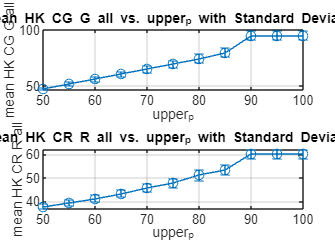

% Definir los valores de upper_p
upper_p_values = 100:-5:50;

% Plotear los resultados
figure;

% Plot para HK_CG_G_all vs. upper_p
subplot(2,1,1);
errorbar(upper_p_values, mean_HK_CG_G_all, std_HK_CG_G_all, 'o-');
xlabel('upper_p');
ylabel('mean HK CG G all');
title('Mean HK CG G all vs. upper_p with Standard Deviation');
grid on;

% Plot para HK_CR_R_all vs. upper_p
subplot(2,1,2);
errorbar(upper_p_values, mean_HK_CR_R_all, std_HK_CR_R_all, 'o-');
xlabel('upper_p');
ylabel('mean HK CR R all');
title('Mean HK CR R all vs. upper_p with Standard Deviation');
grid on;

% Guardar la figura
saveas(gcf, 'results_plot_upper_p.png');